m = -0.314;

syms x y r t c;

m2pi = m/2.*pi;
u1 = diff(m2pi .* log(sqrt(x^2 + (y - 5)^2)), x);
v1 = diff(m2pi .* log(sqrt(x^2 + (y - 5)^2)), y);

u2 = diff(m2pi .* log(sqrt(x^2 + (y + 5)^2)), x);
v2 = diff(m2pi .* log(sqrt(x^2 + (y + 5)^2)), y);

u = simplify(u1 + u2);
v = simplify(v1 + v2);

f = int(u, y) - int(v, x) + c;
f_polar = subs(f, {x, y}, {r .* cos(t), r .* sin(t)});

[x y] = meshgrid([-6:0.5:-0.5 0.5:0.5:6], [-6:0.5:-0.5 0.5:0.5:6]);

ur = subs(u);
vr = subs(v);

f

$$f = c+\frac{157\,\pi \,\mathrm{atan}\left(\frac{x}{y-5}\right)}{1000}+\frac{157\,\pi \,\mathrm{atan}\left(\frac{x}{y+5}\right)}{1000}-\frac{157\,\pi \,\left(\mathrm{atan}\left(\frac{y}{x}-\frac{5}{x}\right)+\mathrm{atan}\left(\frac{y}{x}+\frac{5}{x}\right)\right)}{1000}$$

f_polar

$$f\_polar = \begin{array}{l} c+\frac{157\,\pi \,\mathrm{atan}\left(\frac{r\,\cos\left(t\right)}{r\,\sin\left(t\right)-5}\right)}{1000}+\frac{157\,\pi \,\mathrm{atan}\left(\frac{r\,\cos\left(t\right)}{r\,\sin\left(t\right)+5}\right)}{1000}-\frac{157\,\pi \,\left(\mathrm{atan}\left(\sigma_{2}+\sigma_{1}\right)-\mathrm{atan}\left(\sigma_{2}-\sigma_{1}\right)\right)}{1000}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(t\right)}{\cos\left(t\right)}\\ \sigma_{2}=\frac{5}{r\,\cos\left(t\right)} \end{array}$$

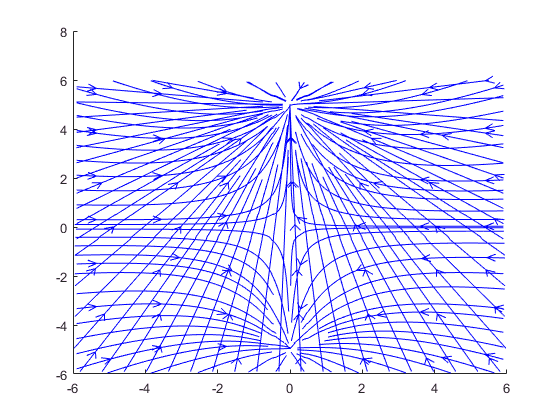

streamslice(x, y, ur, vr)